%% Sampling sparse multiband signals using a multi-coset sampler
% This top-level script (m-file) demonstrates the sampling and recovery of sparse
% multiband signals using the Multi-coset (MC) sampler. The MC sampler was originally
% proposed by P. Feng and Y. Bresler in "Spectrum-blind Minimum-rate Sampling and 
% Reconstruction of Multiband Signals", Proc. IEEE International Conf. on Acoustics,
% Speech, and Signal Processing, vol. 3, pp. 1688-1691, May 1996.

% When the script is executed, MATLAB will generate a discrete multiband signal 
% (simulating a continuous signal), sample it, and estimate (recover) the original 
% signal from its samples. The modeling and system parameters are set in this script. 
% For a complete description of the parameters and of the MC Sampler, refer to the 
% technical report,"Multi-coset Sampling and Recover of Sparse Multiband Signals", 
% accompanying the CTSS Sampling Toolbox or the above reference.

% Copyright (c) 2010 by Michael A Lexa, Mike E Davies, John S Thompson
% Institute of Digital Communications, University of Edinburgh
%
% This work is licenced under the Creative Commons Attribution 3.0
% Unported License. To view a copy of this licence, visit
% http://creativecommons.org/licenses/by/3.0/ or send a letter to
% Creative Commons, 171 Second Street, Suite 300, San Francisco,
% California 94105, USA.

clear

%% Parameters for input signal and multicoset sampler
W=1000; % W/2 Hz is bandlimit of multiband signal class (W=Nyquist rate (Hz))
B=10; % maximum bandwidth of each occupied frequency band (Hz)
K=3; % number of positive disjoint frequency bands present in input signal x
T=20; % duration of observation interval in sec
q=25; % q (uniform) samples collected every L/W seconds (each channel samples W/L Hz)
L=100; % L odd doesn't work
nyqover=1; % controls the length of the simulated multiband signal x (conceptually, x is a vector 
% formed from sampling a continuous-time multiband signal at a rate that is nyqover times more
% than this Nyquist rate. nyqover is a positive integer.) 
SNR=100; % signal-to-noise ratio (in dB)

%% Parameter check
if q>L
 error('q must be less than or equal to L to ensure sub-Nyquist sampling');
end

%% Simulated signal generation, (sub)sampling, support recovery, signal reconstruction
[x,centerfreq,t]=bandsparse(W,B,K,L,nyqover,'modsinc',T); % generate simulated sparse multiband signal (Options: modsinc, filterwhitenoise, chirp)
input_sigP=norm(x)^2/length(x); % compute signal power
input_noiseP=(1/(10^(SNR/10)))*input_sigP; % determine required noise power (variance) wrt input signal power
% s=RandStream.getDefaultStream; 
%reset(s); % uncomment to reset random number generator for repeatable results
w=sqrt(input_noiseP)*(randn(size(x))+1i*randn(size(x))); % generate white Gaussian noise with required variance 
xw=x+w; % add noise

[yw,cw]=mc_sampling(xw,L,q,nyqover); % multi-coset sampling
[eigspectw,centerfreqw_hat,xw_hat,Rw,Phiw_Omega]=mc_recovery(yw,L,W,cw,t,nyqover); % recover support and reconstruct signal

%% Results
fprintf('Nyquist rate %3.3f Hz\n',W);

Nyquist rate 1000.000 Hz


fprintf('System sampling rate %3.3f Hz\n',(q*W)/L);

System sampling rate 250.000 Hz


fprintf('Subsampling factor %3.3f\n',q/L);

Subsampling factor 0.250


fprintf('Input SNR %3.3f dB\n',10*log10(input_sigP./input_noiseP));

Input SNR 100.000 dB


fprintf('True center frequencies of bands with bandwidth %3.2f Hz\n',B);

True center frequencies of bands with bandwidth 10.00 Hz


fprintf('%3.2f\n',sort(centerfreq)); % display true center frequencies of active bands

-152.00
20.00
350.00


fprintf('Center frequencies of declared active bands (spectral resolution %3.2f Hz)\n',W/L);

Center frequencies of declared active bands (spectral resolution 10.00 Hz)


fprintf('%3.2f\n',sort(centerfreqw_hat)); % display recovered center frequencies 

-180.00
-170.00
-160.00
-150.00
-140.00
-130.00
10.00
20.00
30.00
340.00
350.00
360.00


fprintf('Average squared error %2.10f\n',sum((real(x)-real(xw_hat)).^2)*(1/(length(x)-1))); % display average squared error

Average squared error 0.0000010872


fprintf('Column rank of Phi_Omega matrix: %2i\n',rank(Phiw_Omega)) % display rank of Phi

Column rank of Phi_Omega matrix: 12


fprintf('Rank of R matrix: %2i\n',rank(Rw)) % display rank of R

Rank of R matrix: 25


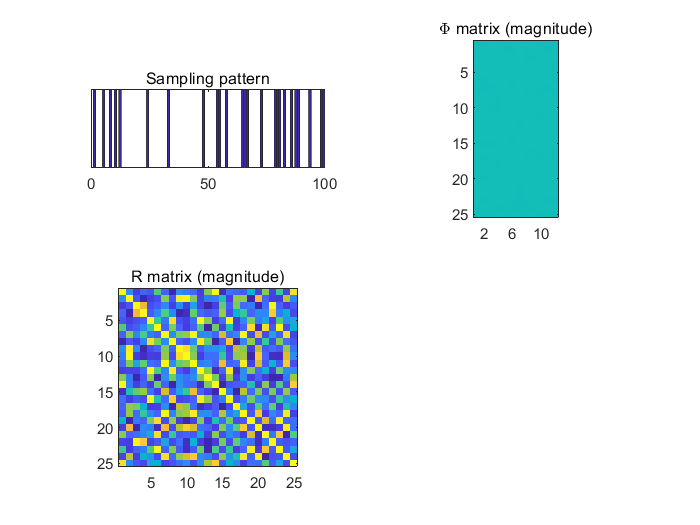

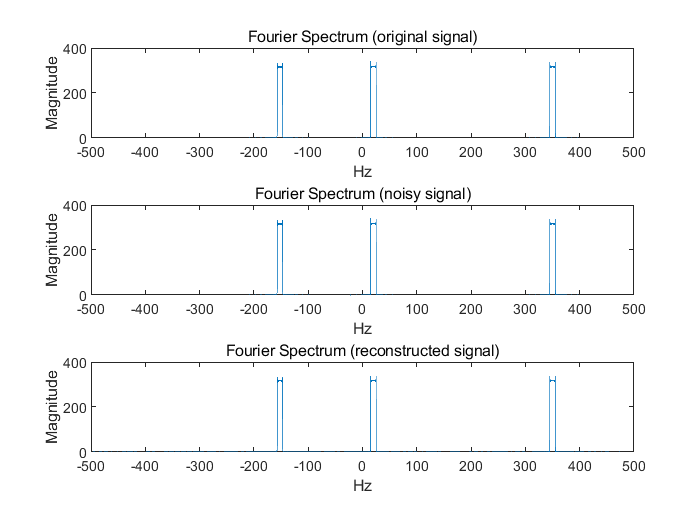

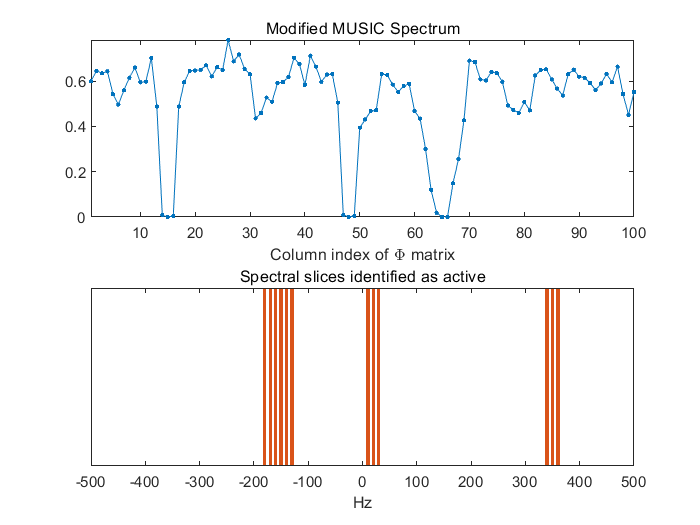

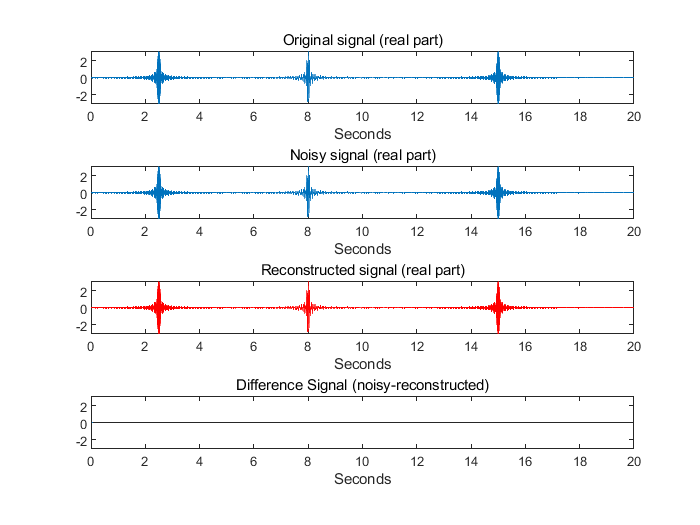


figure % graphically display sampling pattern and Phi matrix
subplot(221); hist(cw,L); 
set(gca,'ytick',[],'DataAspectRatio',[L 3 1]); title('Sampling pattern');
subplot(222); imagesc(abs(Phiw_Omega)); 
axis equal tight; title('\Phi matrix (magnitude)');
subplot(223); imagesc(abs(Rw)); 
axis equal tight; title('R matrix (magnitude)');

figure % plot fft of original signal x and reconstructed signal x_hat
f= (-length(x)/2:length(x)/2-1)./length(x) * (W*nyqover);
h0=subplot(311); plot(f,abs(fftshift(fft(x))),'Marker','none'); title('Fourier Spectrum (original signal)'); 
xlabel('Hz'); ylabel('Magnitude'); xlim([-W/2 W/2]); 
h1=subplot(312); plot(f,abs(fftshift(fft(xw))),'Marker','none'); title('Fourier Spectrum (noisy signal)'); 
xlabel('Hz'); ylabel('Magnitude')
h2=subplot(313); plot(f,abs(fftshift(fft(xw_hat))),'Marker','none'); title('Fourier Spectrum (reconstructed signal)');
xlabel('Hz'); ylabel('Magnitude')
linkaxes([h0 h1 h2])

figure % display support recovery related quantities
subplot(211); plot(abs(eigspectw),'.-'); title('Modified MUSIC Spectrum'); 
xlabel('Column index of \Phi matrix'); axis([1 L 0 max(abs(eigspectw))])
subplot(212); bar(-W/2+W/L:W/L:W/2,histc(centerfreq,-W/2+W/(2*L):W/L:W/2),'EdgeColor','w','FaceColor','r'); 
hold on; bar(-W/2+W/L:W/L:W/2,histc(centerfreqw_hat,-W/2+W/(2*L):W/L:W/2),'EdgeColor','w');  
set(gca,'ytick',[]); xlabel('Hz'); axis([-W/2 W/2 0 1]); title('Spectral slices identified as active') 

figure % plot original multiband signal x and reconstructed signal x_hat
h3=subplot(411); plot(t,real(x),'Marker','none');
xlabel('Seconds'); title('Original signal (real part)');
h4=subplot(412); plot(t,real(xw),'Marker','none');
xlabel('Seconds'); title('Noisy signal (real part)');
h5=subplot(413); plot(t,real(xw_hat),'r','Marker','none'); 
xlabel('Seconds'); title('Reconstructed signal (real part)');
h6=subplot(414); stem(t,real(xw-xw_hat),'Marker','none'); 
xlabel('Seconds'); title('Difference Signal (noisy-reconstructed)');
linkaxes([h3 h4 h5 h6])